# **Análisis de desempeño del sistema de transmisión **

Un problema al acelerar el vehículo son las oscilaciones de la línea de transmisión, es decir, la baja amortiguación en los ejes de transmisión puede causar vibraciones de torsión que provocan una velocidad del vehículo oscilante e incomodidad para el conductor. En el gráfico siguiente se ofrece una ilustración de esto.

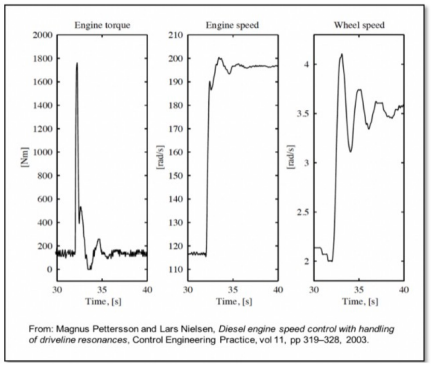

Use los resultados del ejercicio 2 y los archivos Simulink Driveline_ctrl_sim.slx y Driveline_ctrl_design.m para responder si las siguientes afirmaciones son verdadero o falso: 

close all; clear all; clc;

% Parámetros del sistema.
syms s;                         % Variable simbólica.
Jc=6250;                        % Chassis inertia [kgm^2]
Jf=0.625;                       % Flywheel inertia [kgm^2]
ds=1000;                        % Driveshaft damping coefficient [Nms/rad]
cs=75000;                       % Driveshaft spring coefficient [Nm/rad]
i=57;                           % Gear ratio [-]

% Matrices númericas.
A = [-ds/(Jf*i^2)  ds/(Jf*i) -cs/(Jf*i);
     ds/(Jc*i)    -ds/Jc      cs/Jc;
     1/i          -1          0]

A = 	1.0e+03 *

   -0.0005    0.0281   -2.1053
    0.0000   -0.0002    0.0120
    0.0000   -0.0010         0


Bu = [1/Jf;0;0];
Bd = [0;-1/Jc;0];
B = Bu + Bd

B =     1.6000
   -0.0002
         0


C = [0 1 0]

C =      0     1     0


D = [0]

D = 0

I = eye(3);

% Coeficientes polinomio característico.
p_caracteristico = det(s*I-A);
C1_syms = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
C1_double = double(C1_syms); % Coeficientes formato double.
a3 = 0;
a2 = C1_double(1,1);
a1 = C1_double(1,2);

% Coeficientes polinomio deseado.
wn = 6; % Frecuencia natural.
zeta = 1/sqrt(2); % Amortiguamiento relativo.
p_deseado = (s+2*zeta*wn)*(s^2 + 2*zeta*wn*s + wn^2); % Polinomio deseado.
C2_syms = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
C2_double = double(C2_syms); % Coeficientes en formato double.
p3 = C2_double(1,1);
p2 = C2_double(1,2);
p1 = C2_double(1,3);

% Diseño del controlador.
Wr = [B A*B A^2*B] % Matriz de alcanzabilidad.

Wr =     1.6000   -0.7924  -58.9149
   -0.0002    0.0045    0.3358
         0    0.0282   -0.0184


Wr_tilde = inv([1 a1 a2;
                0 1  a1;
                0 0  1])

Wr_tilde =     1.0000   -0.6525  -48.5087
         0    1.0000   -0.6525
         0         0    1.0000


K = [p1-a1 p2-a2 p3-a3]*Wr_tilde*inv(Wr)

K = 	1.0e+03 *

    0.0102    0.3398    1.9480


kr = -1/(C*inv(A-B*K)*B)

kr = 923.0585


%---------------------------------------------------
% For simulation purposes (do not modify)
%---------------------------------------------------
B1=[Bu Bd];                     % Put the B and H matrix together as one matrix B1 (for Simulink implementation purposes) 
C=eye(3);                       % Output all state variables from the model
D=zeros(3,2);                   % Corresponding D matrix
x0=[120 2 0]';                  % Initial conditions for the state variables

**1)** Se han reducido las oscilaciones en la velocidad del vehículo.

Observando la velocidad angular de las ruedas del vehículo, podemos decir que las oscilaciones se han reducido casi por completo.

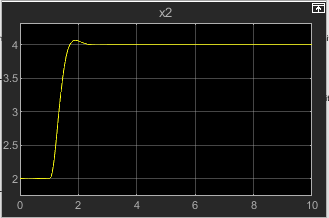

**2)** La velocidad del motor está oscilando.

Se observa que si oscila un poco hasta estabilizarse, de forma violenta. Dado que es el motor quien realiza la acción de control con el fin de controlar la velocidad de las ruedas, sabemos entonces que esta oscilación es necesaria para suavizar la oscilación de las ruedas.

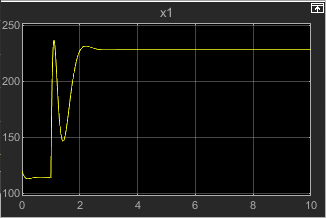

**3)** Se mejora la capacidad de conducción del vehículo.

Si, esto es así que se estabiliza rápidamente la velocidad de las ruedas a la deseada.

Dado que se estabiliza rápidamente la velocidad de las ruedas a la deseadaDado que se estabiliza rápidamente la velocidad de las ruedas a la deseada

**4)** El mismo controlador se puede utilizar para todas las marchas.

No, esto no es así ya que la busqueda de las ganancias del controlador se realizó para una determinada relación de transmición, la cual es distinta para cada marcha.